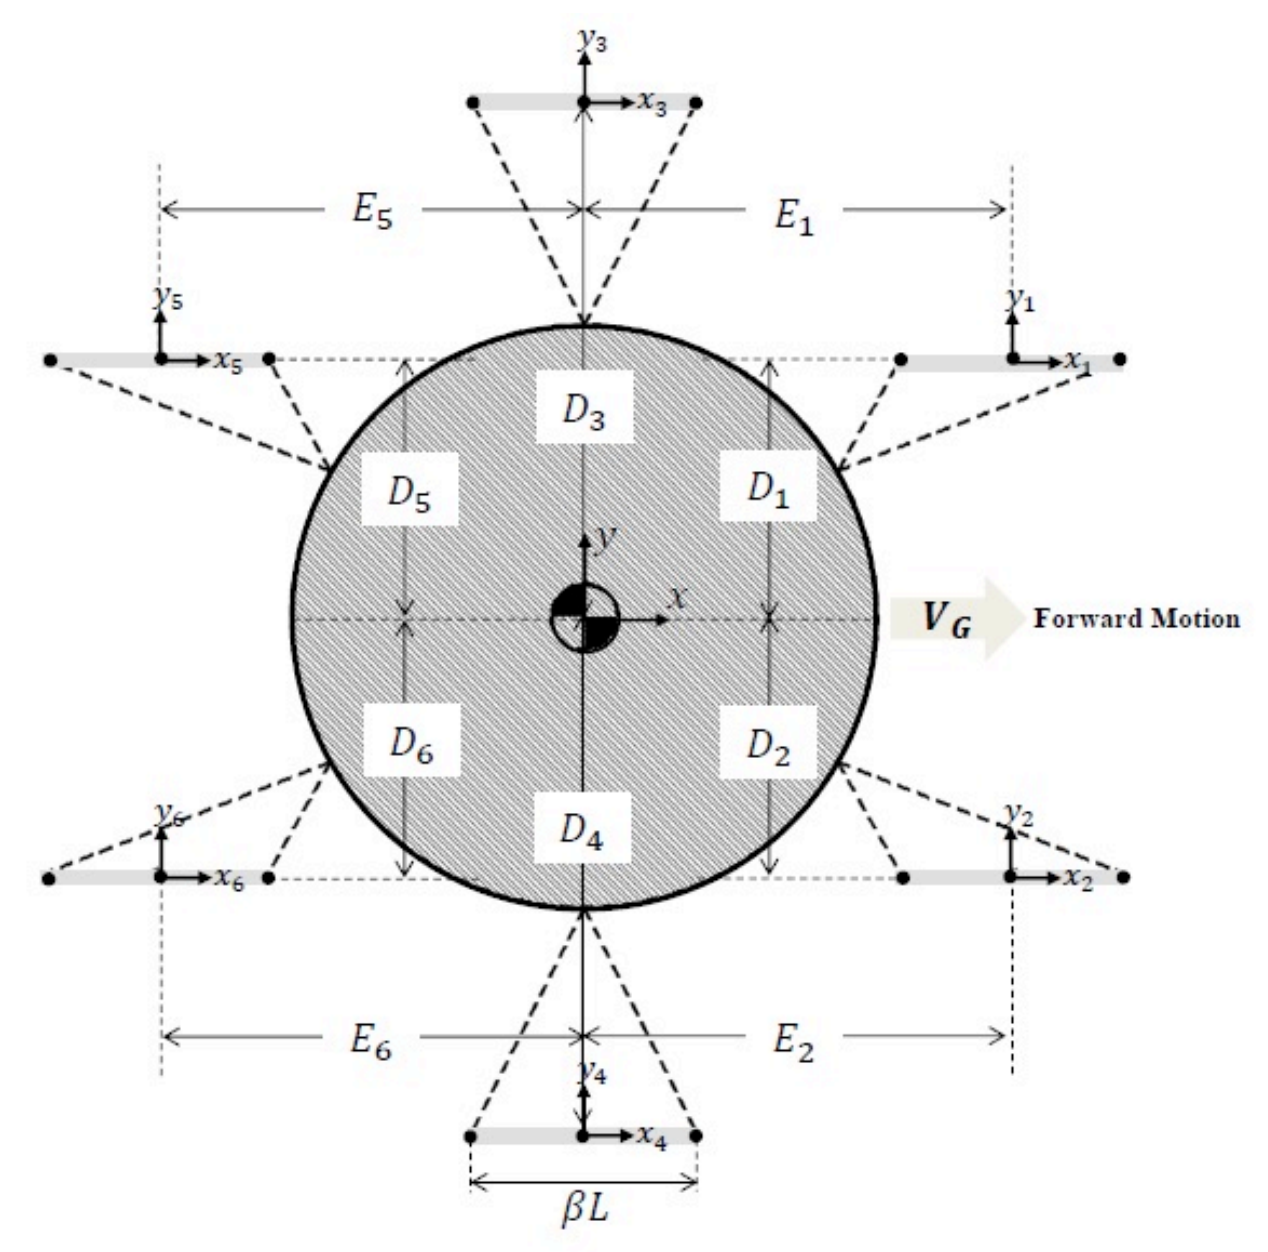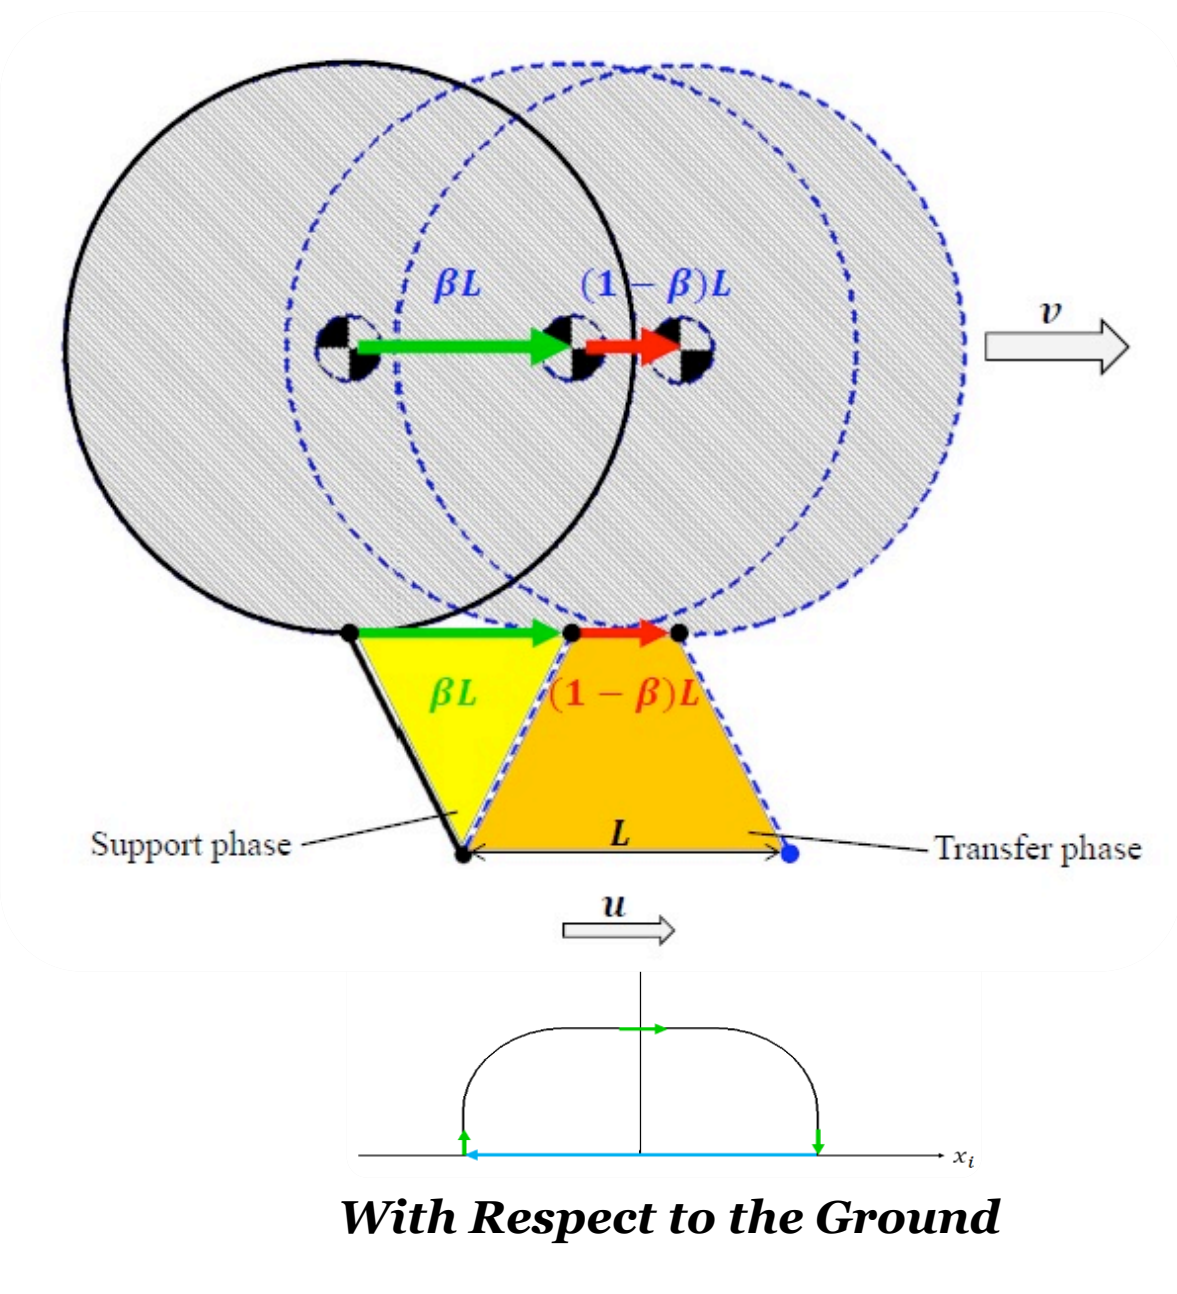

***Step 1: Gait Planning***

The first step was to design the hexapod robot's walking gait. The minimum duty factor is assumed to be 0.5 as that provides the fastest dynamically stable duty factor possible to maintain walking motion. A kinematic phase diagram is shown below:

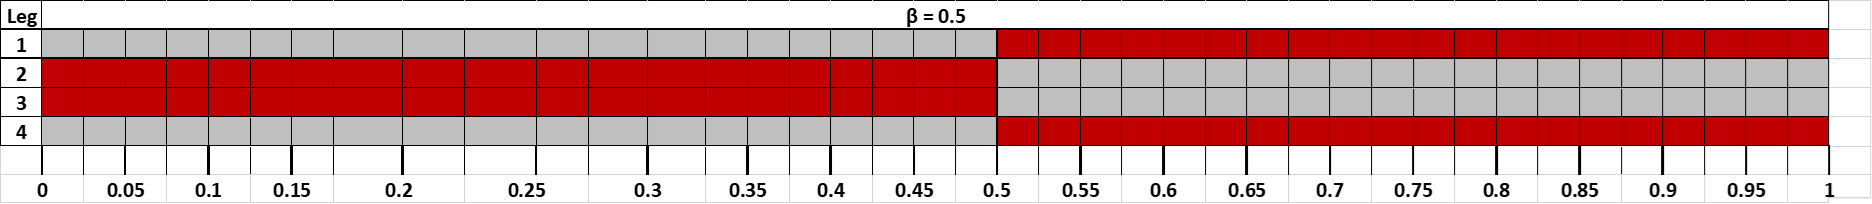

It can be seen that legs 1 and 4 are synchronized together alternating their support and transfer phases with legs 2 and 3. It is assumed the robot has a symmetric gait.

***Step 2:  Foot Trajectory Planning***

Next, we need to design the foot trajectory the tip of the foot will travel during the transfer phase of each step cycle. We are given the contraint that the trajectory must be continuous and the foot must lift off and set down on the ground in a vertical motion. A diagram for the chosen trajectory can be seen in the figure below:

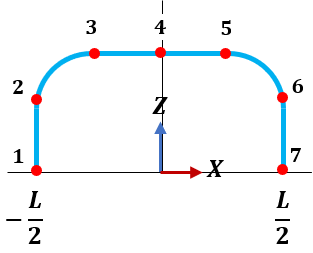

The trajectory was broken up into 7 way points for which we can calcuate a path. The trajector was analyzed to obtain the behavior of the horizontal and vertical movement and velocities. The displacement and velocity profiles for this particular trajectory can be seen below:

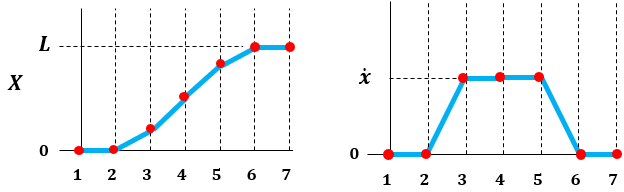

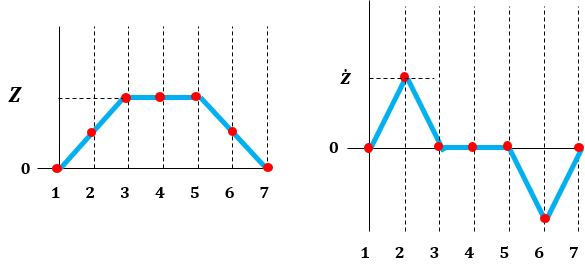

With this in place, we can now begin the process of calculating trajectory curves. First the robot's design parameters are set. The robot is given a height off the ground, a horizontal radius of the body, and a stride length. The cycle time can then be calculated along with the transfer phase cycle time. The maximum velocities and accelerations duringe transfer phase are obtained using the provided graphs. 

% syms t_0 t_f a_0 a_1 a_2 a_3 L
H = 0.5;%(m) Height of robot
R = 0.625; %(m) Radius of robot from center to hip joint from top
L = 0.75; %(m) Stride Length (assumption)
v = 1.5; %(m/s) Velocity of robot body with respect to ground (Given)
B = 0.5; % Minimum stable duty cycle

T = L/v; %(s) Cycle Time
Tt = (1-B)*T; %Transfer Time
Ts = B*T; % Support Time
dt = Tt/6

dt = 0.0417

x_dot_max = L/(3*dt); %(m/s) Max transfer speed in X
z_dot_max = x_dot_max %(m/s) Max transfer speed in Z (assumption)

z_dot_max = 6

x_ddot_max = x_dot_max/dt %(m/s^2) Max transfer acceleration in X

x_ddot_max = 144

z_ddot_max = z_dot_max/dt %(m/s^2) Max transfer acceleration in Z

z_ddot_max = 144


xs_dot_max = L/(5*dt); % (m/s) Max support phase in X
zs_dot_max = 0; % (m/s) Max support speed in Z (leg doesn't lift off ground)
xs_ddot_max = xs_dot_max/dt; % (m/s^2) Max transfer acceleration in X
zs_ddot_max = zs_dot_max/dt; % (m/s^2) Max transfer acceleration in Z (leg doesn't lift off the ground)


Now we can numerically calculate the trajectory way points from the given information.

%Define foot trajectory way points:

%X-direction:
x_ddot_fg_pts = [0 x_ddot_max 0 0 -x_ddot_max 0 0];

x_dot_fg_pts = zeros(1,7);

for i = 1:6
    x_dot_fg_pts(i+1) = x_dot_fg_pts(i) + x_ddot_fg_pts(i)*dt; 
end

% Stance phase:
%X-direction:
xs_ddot_fg_pts = [-xs_ddot_max 0 0 0 0 xs_ddot_max 0  ];
xs_dot_fg_pts = zeros(1,7);
% xs_dot_fg_pts(1) = -xs_dot_max

for i = 1:6
    xs_dot_fg_pts(i+1) = xs_dot_fg_pts(i) + xs_ddot_fg_pts(i)*dt;
end
% xs_dot_fg_pts(1) = -xs_dot_max
%Horizontal Movement of the foot with respect to ground (x_fg):
x_fg_pts = zeros(1,7);
xs_fg_pts = zeros(1,7);

x_fg_pts(1) = -L/2;
xs_fg_pts(1) = L/2;

for i = 1:6
    x_fg_pts(i+1) = x_fg_pts(i) + x_dot_fg_pts(i)*dt + (1/2)*x_ddot_fg_pts(i)*dt^2;
    xs_fg_pts(i+1) = xs_fg_pts(i) + xs_dot_fg_pts(i)*dt + (1/2)*xs_ddot_fg_pts(i)*dt^2;
end


X = [x_fg_pts;x_dot_fg_pts; x_ddot_fg_pts]

X =    -0.3750   -0.3750   -0.2500         0    0.2500    0.3750    0.3750
         0         0    6.0000    6.0000    6.0000         0         0
         0  144.0000         0         0 -144.0000         0         0


Xs = [xs_fg_pts;xs_dot_fg_pts;xs_ddot_fg_pts]

Xs =     0.3750    0.3000    0.1500   -0.0000   -0.1500   -0.3000   -0.3750
         0   -3.6000   -3.6000   -3.6000   -3.6000   -3.6000         0
  -86.4000         0         0         0         0   86.4000         0



%Z-direction:
z_ddot_fg_pts = [z_ddot_max -z_ddot_max 0 0 -z_ddot_max z_ddot_max 0];
z_dot_fg_pts = zeros(1,7);

for i = 1:6
    z_dot_fg_pts(i+1) = z_dot_fg_pts(i) + z_ddot_fg_pts(i)*dt ;
end

%Vertical Movement of the foot with respect to ground (z_fg):
z_fg_pts = zeros(1,7);
zs_fg_pts = zeros(1,7);

for i = 1:6
    z_fg_pts(i+1) = z_fg_pts(i) + z_dot_fg_pts(i)*dt + (1/2)*z_ddot_fg_pts(i)*dt^2;
end

% Stance phase:
%Z-direction:
zs_ddot_fg_pts = [0 0 0 0 0 0 0 ];
zs_dot_fg_pts = zeros(1,7);
for i = 1:6
    zs_dot_fg_pts(i+1) = zs_dot_fg_pts(i) + zs_ddot_fg_pts(i)*dt ;
end

Z = [z_fg_pts;z_dot_fg_pts; z_ddot_fg_pts]

Z =          0    0.1250    0.2500    0.2500    0.2500    0.1250         0
         0    6.0000         0         0         0   -6.0000         0
  144.0000 -144.0000         0         0 -144.0000  144.0000         0


Zs = [zs_fg_pts;zs_dot_fg_pts; zs_ddot_fg_pts];

tpts = 0:dt:Ts

tpts =          0    0.0417    0.0833    0.1250    0.1667    0.2083    0.2500


tvec = linspace(0,Ts,1200)

tvec =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0013    0.0015    0.0017    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0063    0.0065    0.0067    0.0069    0.0071    0.0073    0.0075    0.0077    0.0079    0.0081    0.0083    0.0085    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098    0.0100    0.0102


[q, qd, qdd, pp] = cubicpolytraj([x_fg_pts;z_fg_pts], tpts, tvec,"VelocityBoundaryCondition",[x_dot_fg_pts;z_dot_fg_pts])

q =    -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750
         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0017    0.0018    0.0020    0.0021    0.0023    0.0025    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0041    0.0043    0.0045    0.0048    0.0050    0.0053    0.0055    0.0058    0.0061    0.0063    0.0066    0.0069    0.0072    0

qd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0300    0.0601    0.0901    0.1201    0.1501    0.1802    0.2102    0.2402    0.2702    0.3003    0.3303    0.3603    0.3903    0.4204    0.4504    0.4804    0.5104    0.5405    0.5705    0.6005    0.6305    0.6606    0.6906    0.7206    0.7506    0.7807    0.8107    0.8407    0.8707    0.9008    0.9308    0.9608    0.9908    1.0209    1.0509    1.0809    1.1109    1.1410    1.1710    1.2010    1.2310    1.2611    1.2911    1.3211    1.3511    1.3812    1.4112    1.4412    

qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  1

pp = struct with fields:
      form: 'pp'
    breaks: [-1 0 0.0417 0.0833 0.1250 0.1667 0.2083 0.2500 1.2500]
     coefs: [16×4 double]
    pieces: 8
     order: 4
       dim: 2


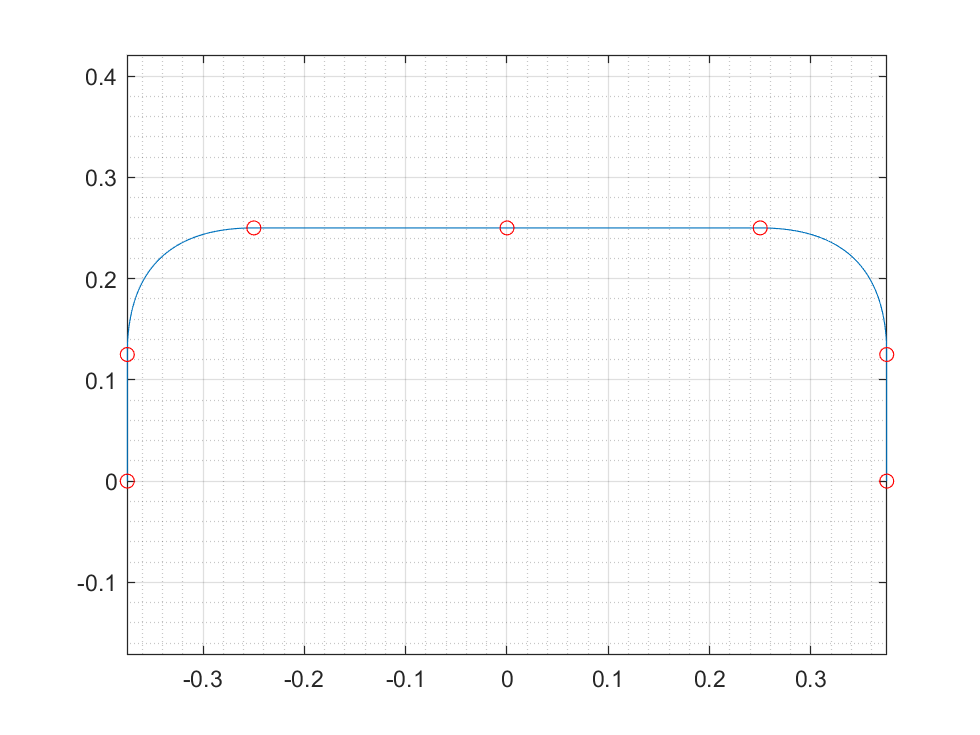

figure()
plot(q(1,:),q(2,:),x_fg_pts,z_fg_pts,'or')
axis equal
grid on
grid minor

With the horizontal and veritcal displacements and velocities calcualted we now can comptute the trajectory made up cubic splines.

%Create Cubic Splines:
clear a q Ttt x_fg  z_fg

%%Horizontal Direction%%
Ttt = 0:dt:Tt; %(s) Time at each way point

%Compute Cubic Polynomial Coefficients:
for i = 1:length(X)-1
    t_0 = Ttt(i);
    t_f = Ttt(i+1);
    q = [X(1:2,i);X(1:2,i+1)];

    M = [1 t_0   t_0^2     t_0^3;
        0   1   2*t_0   3*t_0^2;
        1 t_f   t_f^2     t_f^3;
        0   1   2*t_f   3*t_f^2];

%     a(:,i) = inv(M)*q;
    a(:,i) = M\q;

end

%Make 6 cubic splines for x_fg (horizontal movement of foot wrt ground)
for i = 1:length(a)
    t = linspace(Ttt(i),Ttt(i+1));
    t_c(i,:) = t;
    C_x_fg(i,:) = a(1,i) + a(2,i)*t + a(3,i)*t.^2 + a(4,i)*t.^3;
    C_x_dot_fg(i,:) = a(2,i) + 2*a(3,i)*t + 3*a(4,i)*t.^2;
end

 %% Support Phase:
 %%Horizontal Direction%%
Tts = 0:dt:Ts; %(s) Time at each way point

%Compute Cubic Polynomial Coefficients:
for i = 1:length(Xs)-1
    t_0 = Tts(i);
    t_f = Tts(i+1);
    q = [Xs(1:2,i);Xs(1:2,i+1)];

    M = [1 t_0   t_0^2     t_0^3;
        0   1   2*t_0   3*t_0^2;
        1 t_f   t_f^2     t_f^3;
        0   1   2*t_f   3*t_f^2];

%     as(:,i) = inv(M)*q;
    as(:,i) = M\q;

end

%Make 6 cubic splines for x_fg (horizontal movement of foot wrt ground)
for i = 1:length(as)
    t = linspace(Tts(i),Tts(i+1));
    t_c(i,:) = t;
    C_xs_fg(i,:) = as(1,i) + as(2,i)*t + as(3,i)*t.^2 + as(4,i)*t.^3;
    C_xs_dot_fg(i,:) = as(2,i) + 2*as(3,i)*t + 3*as(4,i)*t.^2;
end




%%Vertical Direction%%

%Compute Cubic Polynomial Coefficients:
for i = 1:length(X)-1
    t_0 = Ttt(i);
    t_f = Ttt(i+1);
    q = [Z(1:2,i);Z(1:2,i+1)];

    M = [1 t_0   t_0^2     t_0^3;
        0   1   2*t_0   3*t_0^2;
        1 t_f   t_f^2     t_f^3;
        0   1   2*t_f   3*t_f^2];

%     a(:,i) = inv(M)*q;
    a(:,i) = M\q;

end

% t = linspace(0,dt);

%Make 6 cubic splines for z_fg (vertical movement of foot wrt ground)
for i = 1:length(a)
    t = linspace(Ttt(i),Ttt(i+1));
    t_c(i,:) = t;
    C_z_fg(i,:) = a(1,i) + a(2,i)*t + a(3,i)*t.^2 + a(4,i)*t.^3;
    C_z_dot_fg(i,:) = a(2,i) + 2*a(3,i)*t + 3*a(4,i)*t.^2;

end

%% Support Phase:
%%Vertical Direction%%

%Compute Cubic Polynomial Coefficients:
for i = 1:length(Zs)-1
    t_0 = Tts(i);
    t_f = Tts(i+1);
    q = [Zs(1:2,i);Zs(1:2,i+1)];

    M = [1 t_0   t_0^2     t_0^3;
        0   1   2*t_0   3*t_0^2;
        1 t_f   t_f^2     t_f^3;
        0   1   2*t_f   3*t_f^2];

%     as(:,i) = inv(M)*q;
    as(:,i) = M\q;

end

% t = linspace(0,dt);

%Make 6 cubic splines for z_fg (vertical movement of foot wrt ground)
for i = 1:length(as)
    t = linspace(Tts(i),Tts(i+1));
    t_c(i,:) = t;
    C_zs_fg(i,:) = as(1,i) + as(2,i)*t + as(3,i)*t.^2 + as(4,i)*t.^3;
    C_zs_dot_fg(i,:) = as(2,i) + 2*as(3,i)*t + 3*as(4,i)*t.^2;

end
% 
% C_xs_fg
% C_xs_dot_fg
% C_zs_fg
% C_zs_dot_fg


With the curves created for the displacement and velocity profiles of the foot tip with respect to the ground, we can now obtain the the coordinates of the foot tip with respect to the robot body.

%Shift coordinate frame to obtain the coorindates of the foot tip with respect to the robot body:
[r,c] = size(C_z_fg);
((1-B)/2)*L

ans = 0.1875

C_x_bg = ones(r,c)*-((1-B)/2)*L

C_x_bg =    -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875
   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875

C_z_bg = ones(r,c)*H;

C_xs_bg = ones(r,c)*-((1-B)/2)*L;
C_zs_bg = ones(r,c)*H;

xdot_bg=v;
zdot_bg=0;

for i = 1:length(a)
    t = linspace(Ttt(i),Ttt(i+1));
    C_x_bg(i,:)=C_x_bg(i,:)+(xdot_bg*ones(1,length(t))).*t
    C_z_bg(i,:)=C_z_bg(i,:)+(zdot_bg*ones(1,length(t))).*t
    
    C_xs_bg(i,:)=C_xs_bg(i,:)+(xdot_bg*ones(1,length(t))).*t;
    C_zs_bg(i,:)=C_zs_bg(i,:)+(zdot_bg*ones(1,length(t))).*t;
    
end

C_x_bg =    -0.1875   -0.1869   -0.1862   -0.1856   -0.1850   -0.1843   -0.1837   -0.1831   -0.1824   -0.1818   -0.1812   -0.1806   -0.1799   -0.1793   -0.1787   -0.1780   -0.1774   -0.1768   -0.1761   -0.1755   -0.1749   -0.1742   -0.1736   -0.1730   -0.1723   -0.1717   -0.1711   -0.1705   -0.1698   -0.1692   -0.1686   -0.1679   -0.1673   -0.1667   -0.1660   -0.1654   -0.1648   -0.1641   -0.1635   -0.1629   -0.1622   -0.1616   -0.1610   -0.1604   -0.1597   -0.1591   -0.1585   -0.1578   -0.1572   -0.1566
   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875   -0.1875

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000

C_x_bg =    -0.1875   -0.1869   -0.1862   -0.1856   -0.1850   -0.1843   -0.1837   -0.1831   -0.1824   -0.1818   -0.1812   -0.1806   -0.1799   -0.1793   -0.1787   -0.1780   -0.1774   -0.1768   -0.1761   -0.1755   -0.1749   -0.1742   -0.1736   -0.1730   -0.1723   -0.1717   -0.1711   -0.1705   -0.1698   -0.1692   -0.1686   -0.1679   -0.1673   -0.1667   -0.1660   -0.1654   -0.1648   -0.1641   -0.1635   -0.1629   -0.1622   -0.1616   -0.1610   -0.1604   -0.1597   -0.1591   -0.1585   -0.1578   -0.1572   -0.1566
   -0.1250   -0.1244   -0.1237   -0.1231   -0.1225   -0.1218   -0.1212   -0.1206   -0.1199   -0.1193   -0.1187   -0.1181   -0.1174   -0.1168   -0.1162   -0.1155   -0.1149   -0.1143   -0.1136   -0.1130   -0.1124   -0.1117   -0.1111   -0.1105   -0.1098   -0.1092   -0.1086   -0.1080   -0.1073   -0.1067   -0.1061   -0.1054   -0.1048   -0.1042   -0.1035   -0.1029   -0.1023   -0.1016   -0.1010   -0.1004   -0.0997   -0.0991   -0.0985   -0.0979   -0.0972   -0.0966   -0.0960   -0.0953   -0.0947

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000

C_x_bg =    -0.1875   -0.1869   -0.1862   -0.1856   -0.1850   -0.1843   -0.1837   -0.1831   -0.1824   -0.1818   -0.1812   -0.1806   -0.1799   -0.1793   -0.1787   -0.1780   -0.1774   -0.1768   -0.1761   -0.1755   -0.1749   -0.1742   -0.1736   -0.1730   -0.1723   -0.1717   -0.1711   -0.1705   -0.1698   -0.1692   -0.1686   -0.1679   -0.1673   -0.1667   -0.1660   -0.1654   -0.1648   -0.1641   -0.1635   -0.1629   -0.1622   -0.1616   -0.1610   -0.1604   -0.1597   -0.1591   -0.1585   -0.1578   -0.1572   -0.1566
   -0.1250   -0.1244   -0.1237   -0.1231   -0.1225   -0.1218   -0.1212   -0.1206   -0.1199   -0.1193   -0.1187   -0.1181   -0.1174   -0.1168   -0.1162   -0.1155   -0.1149   -0.1143   -0.1136   -0.1130   -0.1124   -0.1117   -0.1111   -0.1105   -0.1098   -0.1092   -0.1086   -0.1080   -0.1073   -0.1067   -0.1061   -0.1054   -0.1048   -0.1042   -0.1035   -0.1029   -0.1023   -0.1016   -0.1010   -0.1004   -0.0997   -0.0991   -0.0985   -0.0979   -0.0972   -0.0966   -0.0960   -0.0953   -0.0947

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000

C_x_bg =    -0.1875   -0.1869   -0.1862   -0.1856   -0.1850   -0.1843   -0.1837   -0.1831   -0.1824   -0.1818   -0.1812   -0.1806   -0.1799   -0.1793   -0.1787   -0.1780   -0.1774   -0.1768   -0.1761   -0.1755   -0.1749   -0.1742   -0.1736   -0.1730   -0.1723   -0.1717   -0.1711   -0.1705   -0.1698   -0.1692   -0.1686   -0.1679   -0.1673   -0.1667   -0.1660   -0.1654   -0.1648   -0.1641   -0.1635   -0.1629   -0.1622   -0.1616   -0.1610   -0.1604   -0.1597   -0.1591   -0.1585   -0.1578   -0.1572   -0.1566
   -0.1250   -0.1244   -0.1237   -0.1231   -0.1225   -0.1218   -0.1212   -0.1206   -0.1199   -0.1193   -0.1187   -0.1181   -0.1174   -0.1168   -0.1162   -0.1155   -0.1149   -0.1143   -0.1136   -0.1130   -0.1124   -0.1117   -0.1111   -0.1105   -0.1098   -0.1092   -0.1086   -0.1080   -0.1073   -0.1067   -0.1061   -0.1054   -0.1048   -0.1042   -0.1035   -0.1029   -0.1023   -0.1016   -0.1010   -0.1004   -0.0997   -0.0991   -0.0985   -0.0979   -0.0972   -0.0966   -0.0960   -0.0953   -0.0947

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000

C_x_bg =    -0.1875   -0.1869   -0.1862   -0.1856   -0.1850   -0.1843   -0.1837   -0.1831   -0.1824   -0.1818   -0.1812   -0.1806   -0.1799   -0.1793   -0.1787   -0.1780   -0.1774   -0.1768   -0.1761   -0.1755   -0.1749   -0.1742   -0.1736   -0.1730   -0.1723   -0.1717   -0.1711   -0.1705   -0.1698   -0.1692   -0.1686   -0.1679   -0.1673   -0.1667   -0.1660   -0.1654   -0.1648   -0.1641   -0.1635   -0.1629   -0.1622   -0.1616   -0.1610   -0.1604   -0.1597   -0.1591   -0.1585   -0.1578   -0.1572   -0.1566
   -0.1250   -0.1244   -0.1237   -0.1231   -0.1225   -0.1218   -0.1212   -0.1206   -0.1199   -0.1193   -0.1187   -0.1181   -0.1174   -0.1168   -0.1162   -0.1155   -0.1149   -0.1143   -0.1136   -0.1130   -0.1124   -0.1117   -0.1111   -0.1105   -0.1098   -0.1092   -0.1086   -0.1080   -0.1073   -0.1067   -0.1061   -0.1054   -0.1048   -0.1042   -0.1035   -0.1029   -0.1023   -0.1016   -0.1010   -0.1004   -0.0997   -0.0991   -0.0985   -0.0979   -0.0972   -0.0966   -0.0960   -0.0953   -0.0947

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000

C_x_bg =    -0.1875   -0.1869   -0.1862   -0.1856   -0.1850   -0.1843   -0.1837   -0.1831   -0.1824   -0.1818   -0.1812   -0.1806   -0.1799   -0.1793   -0.1787   -0.1780   -0.1774   -0.1768   -0.1761   -0.1755   -0.1749   -0.1742   -0.1736   -0.1730   -0.1723   -0.1717   -0.1711   -0.1705   -0.1698   -0.1692   -0.1686   -0.1679   -0.1673   -0.1667   -0.1660   -0.1654   -0.1648   -0.1641   -0.1635   -0.1629   -0.1622   -0.1616   -0.1610   -0.1604   -0.1597   -0.1591   -0.1585   -0.1578   -0.1572   -0.1566
   -0.1250   -0.1244   -0.1237   -0.1231   -0.1225   -0.1218   -0.1212   -0.1206   -0.1199   -0.1193   -0.1187   -0.1181   -0.1174   -0.1168   -0.1162   -0.1155   -0.1149   -0.1143   -0.1136   -0.1130   -0.1124   -0.1117   -0.1111   -0.1105   -0.1098   -0.1092   -0.1086   -0.1080   -0.1073   -0.1067   -0.1061   -0.1054   -0.1048   -0.1042   -0.1035   -0.1029   -0.1023   -0.1016   -0.1010   -0.1004   -0.0997   -0.0991   -0.0985   -0.0979   -0.0972   -0.0966   -0.0960   -0.0953   -0.0947

C_z_bg =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000

C_x_fg

C_x_fg =    -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750   -0.3750
   -0.3750   -0.3750   -0.3749   -0.3749   -0.3748   -0.3747   -0.3745   -0.3744   -0.3742   -0.3740   -0.3737   -0.3735   -0.3732   -0.3728   -0.3725   -0.3721   -0.3717   -0.3713   -0.3709   -0.3704   -0.3699   -0.3694   -0.3688   -0.3683   -0.3677   -0.3670   -0.3664   -0.3657   -0.3650   -0.3643   -0.3635   -0.3627   -0.3619   -0.3611   -0.3603   -0.3594   -0.3585   -0.3575   -0.3566   -0.3556   -0.3546   -0.3536   -0.3525   -0.3514   -0.3503   -0.3492   -0.3480   -0.3468   -0.3456


for i = 1:6
    C_x_fb(i,:) = C_x_fg(i,:) -C_x_bg(i,:)
    C_z_fb(i,:) = C_z_fg(i,:) -C_z_bg(i,:)
    
    C_xs_fb(i,:) = C_xs_fg(i,:) +C_xs_bg(i,:);
    C_zs_fb(i,:) = C_zs_fg(i,:) -C_zs_bg(i,:);
end

C_x_fb =    -0.1875   -0.1881   -0.1888   -0.1894   -0.1900   -0.1907   -0.1913   -0.1919   -0.1926   -0.1932   -0.1938   -0.1944   -0.1951   -0.1957   -0.1963   -0.1970   -0.1976   -0.1982   -0.1989   -0.1995   -0.2001   -0.2008   -0.2014   -0.2020   -0.2027   -0.2033   -0.2039   -0.2045   -0.2052   -0.2058   -0.2064   -0.2071   -0.2077   -0.2083   -0.2090   -0.2096   -0.2102   -0.2109   -0.2115   -0.2121   -0.2128   -0.2134   -0.2140   -0.2146   -0.2153   -0.2159   -0.2165   -0.2172   -0.2178   -0.2184


C_z_fb =    -0.5000   -0.5000   -0.4999   -0.4999   -0.4998   -0.4997   -0.4995   -0.4994   -0.4992   -0.4990   -0.4987   -0.4985   -0.4982   -0.4978   -0.4975   -0.4971   -0.4967   -0.4963   -0.4959   -0.4954   -0.4949   -0.4944   -0.4938   -0.4933   -0.4927   -0.4920   -0.4914   -0.4907   -0.4900   -0.4893   -0.4885   -0.4877   -0.4869   -0.4861   -0.4853   -0.4844   -0.4835   -0.4825   -0.4816   -0.4806   -0.4796   -0.4786   -0.4775   -0.4764   -0.4753   -0.4742   -0.4730   -0.4718   -0.4706   -0.4694


C_x_fb =    -0.1875   -0.1881   -0.1888   -0.1894   -0.1900   -0.1907   -0.1913   -0.1919   -0.1926   -0.1932   -0.1938   -0.1944   -0.1951   -0.1957   -0.1963   -0.1970   -0.1976   -0.1982   -0.1989   -0.1995   -0.2001   -0.2008   -0.2014   -0.2020   -0.2027   -0.2033   -0.2039   -0.2045   -0.2052   -0.2058   -0.2064   -0.2071   -0.2077   -0.2083   -0.2090   -0.2096   -0.2102   -0.2109   -0.2115   -0.2121   -0.2128   -0.2134   -0.2140   -0.2146   -0.2153   -0.2159   -0.2165   -0.2172   -0.2178   -0.2184
   -0.2500   -0.2506   -0.2512   -0.2518   -0.2523   -0.2528   -0.2533   -0.2538   -0.2542   -0.2546   -0.2550   -0.2554   -0.2557   -0.2561   -0.2563   -0.2566   -0.2568   -0.2570   -0.2572   -0.2574   -0.2575   -0.2576   -0.2577   -0.2578   -0.2578   -0.2578   -0.2578   -0.2577   -0.2577   -0.2576   -0.2575   -0.2573   -0.2571   -0.2569   -0.2567   -0.2565   -0.2562   -0.2559   -0.2556   -0.2552   -0.2548   -0.2544   -0.2540   -0.2536   -0.2531   -0.2526   -0.2521   -0.2515   -0.2509

C_z_fb =    -0.5000   -0.5000   -0.4999   -0.4999   -0.4998   -0.4997   -0.4995   -0.4994   -0.4992   -0.4990   -0.4987   -0.4985   -0.4982   -0.4978   -0.4975   -0.4971   -0.4967   -0.4963   -0.4959   -0.4954   -0.4949   -0.4944   -0.4938   -0.4933   -0.4927   -0.4920   -0.4914   -0.4907   -0.4900   -0.4893   -0.4885   -0.4877   -0.4869   -0.4861   -0.4853   -0.4844   -0.4835   -0.4825   -0.4816   -0.4806   -0.4796   -0.4786   -0.4775   -0.4764   -0.4753   -0.4742   -0.4730   -0.4718   -0.4706   -0.4694
   -0.3750   -0.3725   -0.3700   -0.3675   -0.3651   -0.3627   -0.3603   -0.3579   -0.3556   -0.3533   -0.3510   -0.3488   -0.3465   -0.3443   -0.3421   -0.3400   -0.3379   -0.3358   -0.3337   -0.3316   -0.3296   -0.3276   -0.3256   -0.3237   -0.3217   -0.3198   -0.3180   -0.3161   -0.3143   -0.3125   -0.3107   -0.3090   -0.3073   -0.3056   -0.3039   -0.3022   -0.3006   -0.2990   -0.2975   -0.2959   -0.2944   -0.2929   -0.2914   -0.2900   -0.2886   -0.2872   -0.2858   -0.2845   -0.2832

C_x_fb =    -0.1875   -0.1881   -0.1888   -0.1894   -0.1900   -0.1907   -0.1913   -0.1919   -0.1926   -0.1932   -0.1938   -0.1944   -0.1951   -0.1957   -0.1963   -0.1970   -0.1976   -0.1982   -0.1989   -0.1995   -0.2001   -0.2008   -0.2014   -0.2020   -0.2027   -0.2033   -0.2039   -0.2045   -0.2052   -0.2058   -0.2064   -0.2071   -0.2077   -0.2083   -0.2090   -0.2096   -0.2102   -0.2109   -0.2115   -0.2121   -0.2128   -0.2134   -0.2140   -0.2146   -0.2153   -0.2159   -0.2165   -0.2172   -0.2178   -0.2184
   -0.2500   -0.2506   -0.2512   -0.2518   -0.2523   -0.2528   -0.2533   -0.2538   -0.2542   -0.2546   -0.2550   -0.2554   -0.2557   -0.2561   -0.2563   -0.2566   -0.2568   -0.2570   -0.2572   -0.2574   -0.2575   -0.2576   -0.2577   -0.2578   -0.2578   -0.2578   -0.2578   -0.2577   -0.2577   -0.2576   -0.2575   -0.2573   -0.2571   -0.2569   -0.2567   -0.2565   -0.2562   -0.2559   -0.2556   -0.2552   -0.2548   -0.2544   -0.2540   -0.2536   -0.2531   -0.2526   -0.2521   -0.2515   -0.2509

C_z_fb =    -0.5000   -0.5000   -0.4999   -0.4999   -0.4998   -0.4997   -0.4995   -0.4994   -0.4992   -0.4990   -0.4987   -0.4985   -0.4982   -0.4978   -0.4975   -0.4971   -0.4967   -0.4963   -0.4959   -0.4954   -0.4949   -0.4944   -0.4938   -0.4933   -0.4927   -0.4920   -0.4914   -0.4907   -0.4900   -0.4893   -0.4885   -0.4877   -0.4869   -0.4861   -0.4853   -0.4844   -0.4835   -0.4825   -0.4816   -0.4806   -0.4796   -0.4786   -0.4775   -0.4764   -0.4753   -0.4742   -0.4730   -0.4718   -0.4706   -0.4694
   -0.3750   -0.3725   -0.3700   -0.3675   -0.3651   -0.3627   -0.3603   -0.3579   -0.3556   -0.3533   -0.3510   -0.3488   -0.3465   -0.3443   -0.3421   -0.3400   -0.3379   -0.3358   -0.3337   -0.3316   -0.3296   -0.3276   -0.3256   -0.3237   -0.3217   -0.3198   -0.3180   -0.3161   -0.3143   -0.3125   -0.3107   -0.3090   -0.3073   -0.3056   -0.3039   -0.3022   -0.3006   -0.2990   -0.2975   -0.2959   -0.2944   -0.2929   -0.2914   -0.2900   -0.2886   -0.2872   -0.2858   -0.2845   -0.2832

C_x_fb =    -0.1875   -0.1881   -0.1888   -0.1894   -0.1900   -0.1907   -0.1913   -0.1919   -0.1926   -0.1932   -0.1938   -0.1944   -0.1951   -0.1957   -0.1963   -0.1970   -0.1976   -0.1982   -0.1989   -0.1995   -0.2001   -0.2008   -0.2014   -0.2020   -0.2027   -0.2033   -0.2039   -0.2045   -0.2052   -0.2058   -0.2064   -0.2071   -0.2077   -0.2083   -0.2090   -0.2096   -0.2102   -0.2109   -0.2115   -0.2121   -0.2128   -0.2134   -0.2140   -0.2146   -0.2153   -0.2159   -0.2165   -0.2172   -0.2178   -0.2184
   -0.2500   -0.2506   -0.2512   -0.2518   -0.2523   -0.2528   -0.2533   -0.2538   -0.2542   -0.2546   -0.2550   -0.2554   -0.2557   -0.2561   -0.2563   -0.2566   -0.2568   -0.2570   -0.2572   -0.2574   -0.2575   -0.2576   -0.2577   -0.2578   -0.2578   -0.2578   -0.2578   -0.2577   -0.2577   -0.2576   -0.2575   -0.2573   -0.2571   -0.2569   -0.2567   -0.2565   -0.2562   -0.2559   -0.2556   -0.2552   -0.2548   -0.2544   -0.2540   -0.2536   -0.2531   -0.2526   -0.2521   -0.2515   -0.2509

C_z_fb =    -0.5000   -0.5000   -0.4999   -0.4999   -0.4998   -0.4997   -0.4995   -0.4994   -0.4992   -0.4990   -0.4987   -0.4985   -0.4982   -0.4978   -0.4975   -0.4971   -0.4967   -0.4963   -0.4959   -0.4954   -0.4949   -0.4944   -0.4938   -0.4933   -0.4927   -0.4920   -0.4914   -0.4907   -0.4900   -0.4893   -0.4885   -0.4877   -0.4869   -0.4861   -0.4853   -0.4844   -0.4835   -0.4825   -0.4816   -0.4806   -0.4796   -0.4786   -0.4775   -0.4764   -0.4753   -0.4742   -0.4730   -0.4718   -0.4706   -0.4694
   -0.3750   -0.3725   -0.3700   -0.3675   -0.3651   -0.3627   -0.3603   -0.3579   -0.3556   -0.3533   -0.3510   -0.3488   -0.3465   -0.3443   -0.3421   -0.3400   -0.3379   -0.3358   -0.3337   -0.3316   -0.3296   -0.3276   -0.3256   -0.3237   -0.3217   -0.3198   -0.3180   -0.3161   -0.3143   -0.3125   -0.3107   -0.3090   -0.3073   -0.3056   -0.3039   -0.3022   -0.3006   -0.2990   -0.2975   -0.2959   -0.2944   -0.2929   -0.2914   -0.2900   -0.2886   -0.2872   -0.2858   -0.2845   -0.2832

C_x_fb =    -0.1875   -0.1881   -0.1888   -0.1894   -0.1900   -0.1907   -0.1913   -0.1919   -0.1926   -0.1932   -0.1938   -0.1944   -0.1951   -0.1957   -0.1963   -0.1970   -0.1976   -0.1982   -0.1989   -0.1995   -0.2001   -0.2008   -0.2014   -0.2020   -0.2027   -0.2033   -0.2039   -0.2045   -0.2052   -0.2058   -0.2064   -0.2071   -0.2077   -0.2083   -0.2090   -0.2096   -0.2102   -0.2109   -0.2115   -0.2121   -0.2128   -0.2134   -0.2140   -0.2146   -0.2153   -0.2159   -0.2165   -0.2172   -0.2178   -0.2184
   -0.2500   -0.2506   -0.2512   -0.2518   -0.2523   -0.2528   -0.2533   -0.2538   -0.2542   -0.2546   -0.2550   -0.2554   -0.2557   -0.2561   -0.2563   -0.2566   -0.2568   -0.2570   -0.2572   -0.2574   -0.2575   -0.2576   -0.2577   -0.2578   -0.2578   -0.2578   -0.2578   -0.2577   -0.2577   -0.2576   -0.2575   -0.2573   -0.2571   -0.2569   -0.2567   -0.2565   -0.2562   -0.2559   -0.2556   -0.2552   -0.2548   -0.2544   -0.2540   -0.2536   -0.2531   -0.2526   -0.2521   -0.2515   -0.2509

C_z_fb =    -0.5000   -0.5000   -0.4999   -0.4999   -0.4998   -0.4997   -0.4995   -0.4994   -0.4992   -0.4990   -0.4987   -0.4985   -0.4982   -0.4978   -0.4975   -0.4971   -0.4967   -0.4963   -0.4959   -0.4954   -0.4949   -0.4944   -0.4938   -0.4933   -0.4927   -0.4920   -0.4914   -0.4907   -0.4900   -0.4893   -0.4885   -0.4877   -0.4869   -0.4861   -0.4853   -0.4844   -0.4835   -0.4825   -0.4816   -0.4806   -0.4796   -0.4786   -0.4775   -0.4764   -0.4753   -0.4742   -0.4730   -0.4718   -0.4706   -0.4694
   -0.3750   -0.3725   -0.3700   -0.3675   -0.3651   -0.3627   -0.3603   -0.3579   -0.3556   -0.3533   -0.3510   -0.3488   -0.3465   -0.3443   -0.3421   -0.3400   -0.3379   -0.3358   -0.3337   -0.3316   -0.3296   -0.3276   -0.3256   -0.3237   -0.3217   -0.3198   -0.3180   -0.3161   -0.3143   -0.3125   -0.3107   -0.3090   -0.3073   -0.3056   -0.3039   -0.3022   -0.3006   -0.2990   -0.2975   -0.2959   -0.2944   -0.2929   -0.2914   -0.2900   -0.2886   -0.2872   -0.2858   -0.2845   -0.2832

C_x_fb =    -0.1875   -0.1881   -0.1888   -0.1894   -0.1900   -0.1907   -0.1913   -0.1919   -0.1926   -0.1932   -0.1938   -0.1944   -0.1951   -0.1957   -0.1963   -0.1970   -0.1976   -0.1982   -0.1989   -0.1995   -0.2001   -0.2008   -0.2014   -0.2020   -0.2027   -0.2033   -0.2039   -0.2045   -0.2052   -0.2058   -0.2064   -0.2071   -0.2077   -0.2083   -0.2090   -0.2096   -0.2102   -0.2109   -0.2115   -0.2121   -0.2128   -0.2134   -0.2140   -0.2146   -0.2153   -0.2159   -0.2165   -0.2172   -0.2178   -0.2184
   -0.2500   -0.2506   -0.2512   -0.2518   -0.2523   -0.2528   -0.2533   -0.2538   -0.2542   -0.2546   -0.2550   -0.2554   -0.2557   -0.2561   -0.2563   -0.2566   -0.2568   -0.2570   -0.2572   -0.2574   -0.2575   -0.2576   -0.2577   -0.2578   -0.2578   -0.2578   -0.2578   -0.2577   -0.2577   -0.2576   -0.2575   -0.2573   -0.2571   -0.2569   -0.2567   -0.2565   -0.2562   -0.2559   -0.2556   -0.2552   -0.2548   -0.2544   -0.2540   -0.2536   -0.2531   -0.2526   -0.2521   -0.2515   -0.2509

C_z_fb =    -0.5000   -0.5000   -0.4999   -0.4999   -0.4998   -0.4997   -0.4995   -0.4994   -0.4992   -0.4990   -0.4987   -0.4985   -0.4982   -0.4978   -0.4975   -0.4971   -0.4967   -0.4963   -0.4959   -0.4954   -0.4949   -0.4944   -0.4938   -0.4933   -0.4927   -0.4920   -0.4914   -0.4907   -0.4900   -0.4893   -0.4885   -0.4877   -0.4869   -0.4861   -0.4853   -0.4844   -0.4835   -0.4825   -0.4816   -0.4806   -0.4796   -0.4786   -0.4775   -0.4764   -0.4753   -0.4742   -0.4730   -0.4718   -0.4706   -0.4694
   -0.3750   -0.3725   -0.3700   -0.3675   -0.3651   -0.3627   -0.3603   -0.3579   -0.3556   -0.3533   -0.3510   -0.3488   -0.3465   -0.3443   -0.3421   -0.3400   -0.3379   -0.3358   -0.3337   -0.3316   -0.3296   -0.3276   -0.3256   -0.3237   -0.3217   -0.3198   -0.3180   -0.3161   -0.3143   -0.3125   -0.3107   -0.3090   -0.3073   -0.3056   -0.3039   -0.3022   -0.3006   -0.2990   -0.2975   -0.2959   -0.2944   -0.2929   -0.2914   -0.2900   -0.2886   -0.2872   -0.2858   -0.2845   -0.2832

Using the newly formed position and velocity curves, we can now show the position and velocity graphs of a single leg foot tip over the trajectory. 

- Plot (1,1) shows the horizontal velocity of the foot with respect to the ground over time. 

- Plot (1,2) shows the vertical velocity of the foot tip with respect to ground over time. 

- Plot (2,1) shows the horizontal movement of the foot with respect to the ground over time. 

- Plot (2,2) shows the vertical movement of the foot tip with respect to ground over time. 

- Plot (3,1) shows the vertical position over the horizontal position of the foot tip with respect to the ground. 

- Plot (3,2) shows the vertical position over the horizontal position of the foot tip with respect to the robot body. 

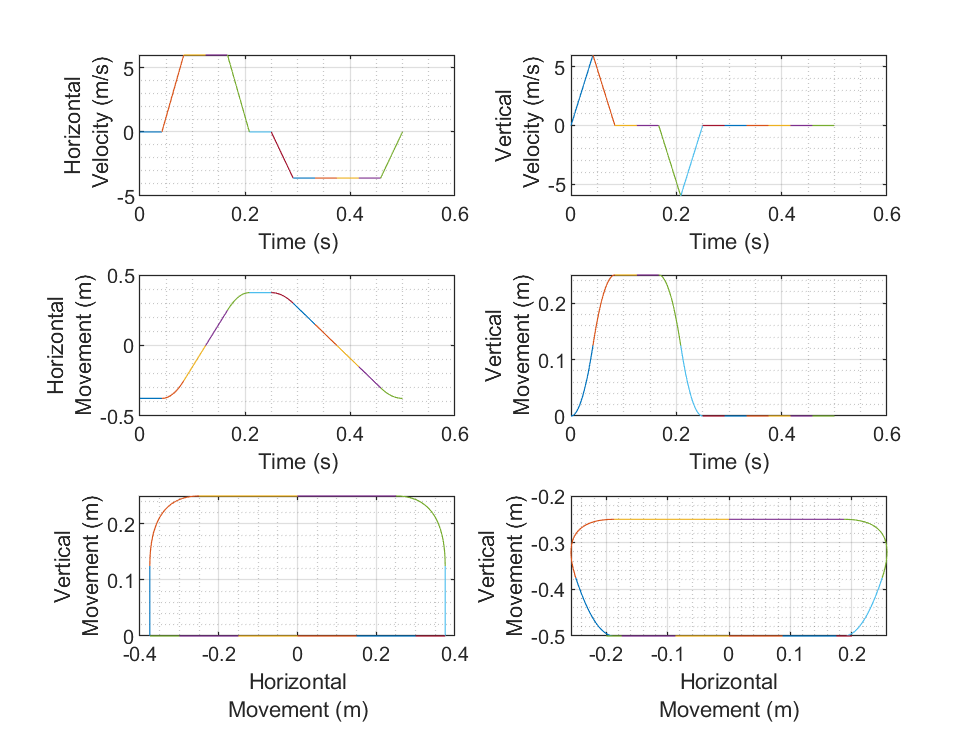

figure
subplot(3,2,1)
plot(t_c(1,:),C_x_dot_fg(1,:),t_c(2,:), C_x_dot_fg(2,:), t_c(3,:), C_x_dot_fg(3,:),t_c(4,:), C_x_dot_fg(4,:),t_c(5,:), C_x_dot_fg(5,:),t_c(6,:), C_x_dot_fg(6,:),t_c(1,:)+Tt,C_xs_dot_fg(1,:),t_c(2,:)+Tt, C_xs_dot_fg(2,:), t_c(3,:)+Tt, C_xs_dot_fg(3,:),t_c(4,:)+Tt, C_xs_dot_fg(4,:),t_c(5,:)+Tt, C_xs_dot_fg(5,:),t_c(6,:)+Tt, C_xs_dot_fg(6,:))
grid on
grid minor
xlabel('Time (s)')
ylabel("Horizontal"+newline+" Velocity (m/s)")

subplot(3,2,2)
plot(t_c(1,:),C_z_dot_fg(1,:),t_c(2,:), C_z_dot_fg(2,:), t_c(3,:), C_z_dot_fg(3,:),t_c(4,:), C_z_dot_fg(4,:),t_c(5,:), C_z_dot_fg(5,:),t_c(6,:), C_z_dot_fg(6,:),t_c(1,:)+Tt,C_zs_dot_fg(1,:),t_c(2,:)+Tt, C_zs_dot_fg(2,:), t_c(3,:)+Tt, C_zs_dot_fg(3,:),t_c(4,:)+Tt, C_zs_dot_fg(4,:),t_c(5,:)+Tt, C_zs_dot_fg(5,:),t_c(6,:)+Tt, C_zs_dot_fg(6,:))
grid on
grid minor
xlabel('Time (s)')
ylabel("Vertical"+newline+" Velocity (m/s)")

subplot(3,2,3)
plot(t_c(1,:),C_x_fg(1,:),t_c(2,:), C_x_fg(2,:), t_c(3,:), C_x_fg(3,:),t_c(4,:), C_x_fg(4,:),t_c(5,:), C_x_fg(5,:),t_c(6,:), C_x_fg(6,:),t_c(1,:)+Tt,C_xs_fg(1,:),t_c(2,:)+Tt, C_xs_fg(2,:), t_c(3,:)+Tt, C_xs_fg(3,:),t_c(4,:)+Tt, C_xs_fg(4,:),t_c(5,:)+Tt, C_xs_fg(5,:),t_c(6,:)+Tt, C_xs_fg(6,:))
grid on
grid minor
xlabel('Time (s)')
ylabel("Horizontal" +newline+ "Movement (m)")

subplot(3,2,4)
plot(t_c(1,:),C_z_fg(1,:),t_c(2,:), C_z_fg(2,:), t_c(3,:), C_z_fg(3,:),t_c(4,:), C_z_fg(4,:),t_c(5,:), C_z_fg(5,:),t_c(6,:), C_z_fg(6,:),t_c(1,:)+Tt,C_zs_fg(1,:),t_c(2,:)+Tt, C_zs_fg(2,:), t_c(3,:)+Tt, C_zs_fg(3,:),t_c(4,:)+Tt, C_zs_fg(4,:),t_c(5,:)+Tt, C_zs_fg(5,:),t_c(6,:)+Tt, C_zs_fg(6,:))
grid on
grid minor
xlabel('Time (s)')
ylabel("Vertical" +newline+ "Movement (m)")

subplot(3,2,5)
plot(C_x_fg(1,:),C_z_fg(1,:), C_x_fg(2,:), C_z_fg(2,:), C_x_fg(3,:),C_z_fg(3,:), C_x_fg(4,:),C_z_fg(4,:), C_x_fg(5,:),C_z_fg(5,:), C_x_fg(6,:),C_z_fg(6,:),C_xs_fg(1,:),C_zs_fg(1,:), C_xs_fg(2,:), C_zs_fg(2,:), C_xs_fg(3,:),C_zs_fg(3,:), C_xs_fg(4,:),C_zs_fg(4,:), C_xs_fg(5,:),C_zs_fg(5,:), C_xs_fg(6,:),C_zs_fg(6,:))
grid on
grid minor
xlabel("Horizontal" +newline+ "Movement (m)")
ylabel("Vertical" +newline+ "Movement (m)")

subplot(3,2,6)
plot(C_x_fb(1,:),C_z_fb(1,:), C_x_fb(2,:), C_z_fb(2,:), C_x_fb(3,:),C_z_fb(3,:), C_x_fb(4,:),C_z_fb(4,:), C_x_fb(5,:),C_z_fb(5,:), C_x_fb(6,:),C_z_fb(6,:),C_xs_fb(1,:),C_zs_fb(1,:), C_xs_fb(2,:), C_zs_fb(2,:), C_xs_fb(3,:),C_zs_fb(3,:), C_xs_fb(4,:),C_zs_fb(4,:), C_xs_fb(5,:),C_zs_fb(5,:), C_xs_fb(6,:),C_zs_fb(6,:))
grid on
grid minor
xlabel("Horizontal" +newline+ "Movement (m)")
ylabel("Vertical" +newline+ "Movement (m)")